# TEST71 

## Import the data into MATLAB

fname = 'test71.bin'; % binary data file name
sig_len = 18; % signal length in samples
num_ch = 15; % number of channels
num_trl = 137; % number of trials
fs = 200; % sampling frequency (Hz)

dat = readdat(fname, sig_len, num_ch, num_trl);

## Preprocess the data

dat_pre = pre_sube(dat); % subtract ensemble mean

## AIC test

win_len = 10; % window length
max_order = 8; % maxium model order
AIC = aic_test(dat_pre, win_len, max_order);

Plot the result

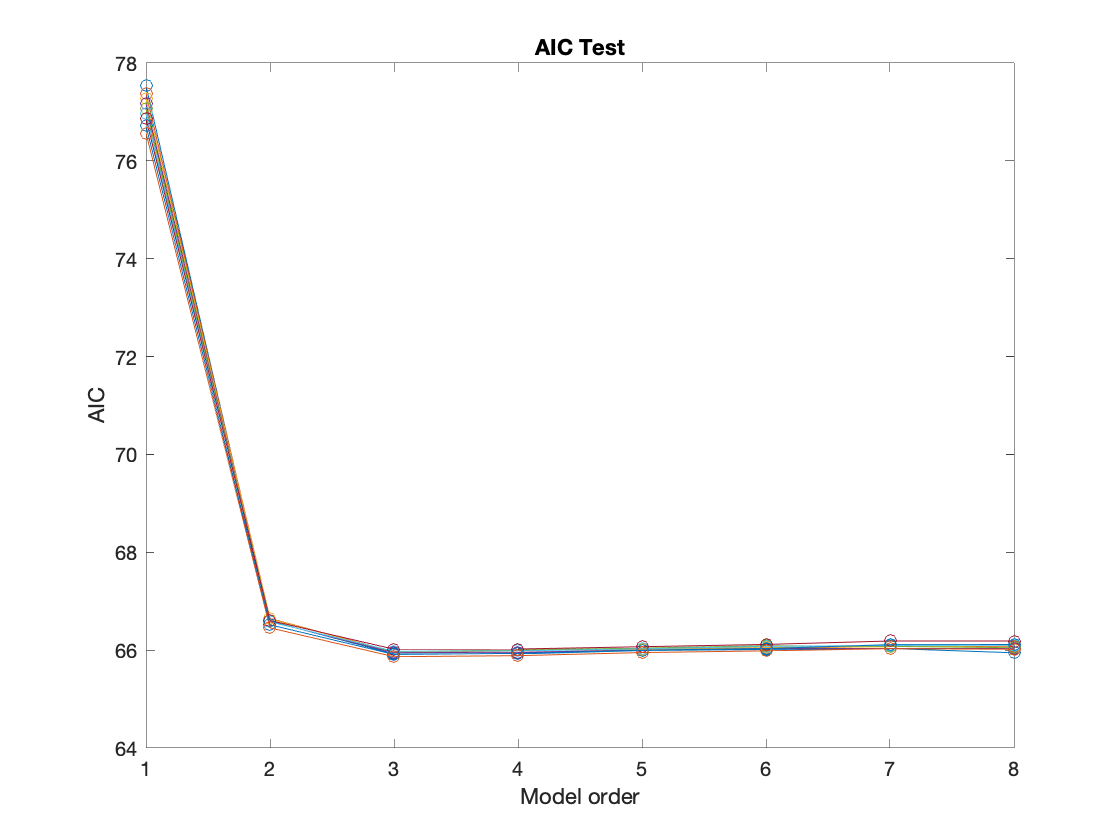

figure
plot(AIC', '-o')
xlabel('Model order')
ylabel('AIC')
title('AIC Test')

## Build moving window multivariate AR model

model_ord = 5; % model order
startp = 1; % start position in samples
endp = 15; % end position

Find the window center

num_win = endp-win_len+1;
win_c = (1/2+(0:(num_win-1)))*win_len/fs*1000; % window centers in ms

Calculate the model

[A, Ve] = mov_mul_model(dat_pre, model_ord, startp, endp, win_len);

## Model tests

### Consistency test

ratio = consistencytest(dat_pre, A, Ve);

Plot the result

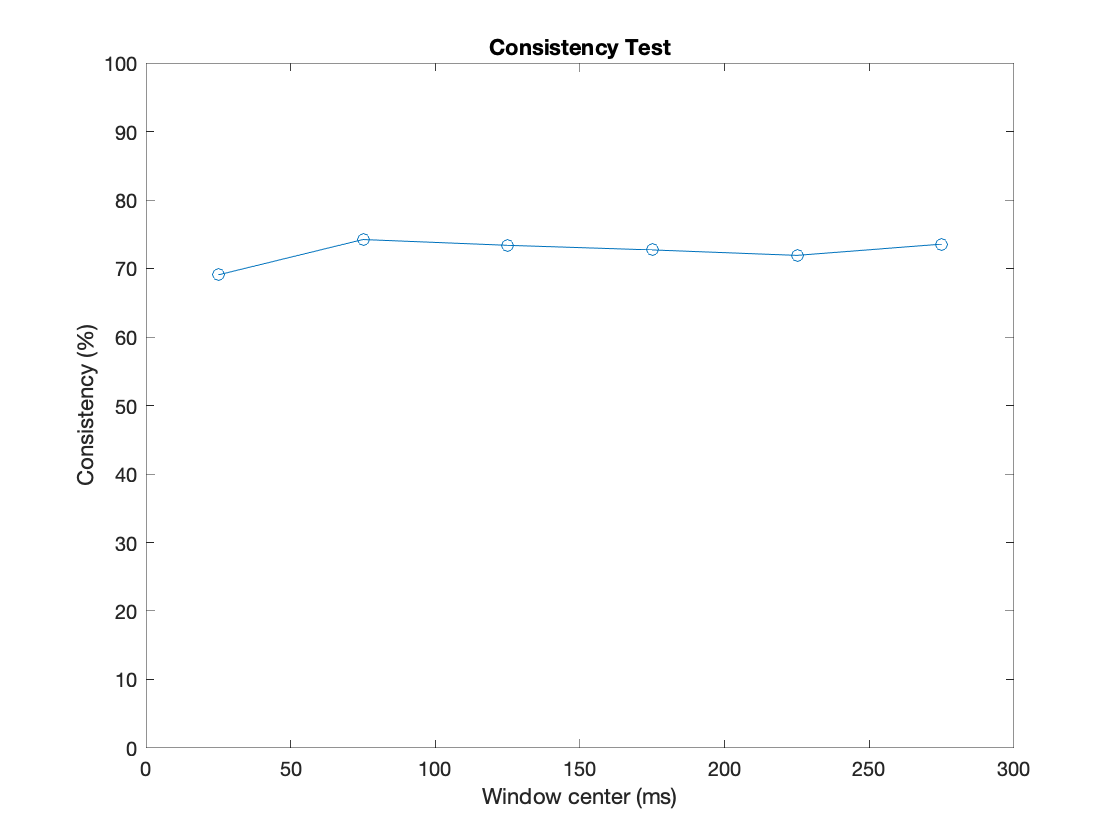

figure
plot(win_c, ratio, '-o')
ylim([0, 100])
title('Consistency Test')
xlabel('Window center (ms)')
ylabel('Consistency (%)')

### Whiteness test

resid = whitenesstest(dat_pre, win_len, model_ord, startp, endp);

plot the result

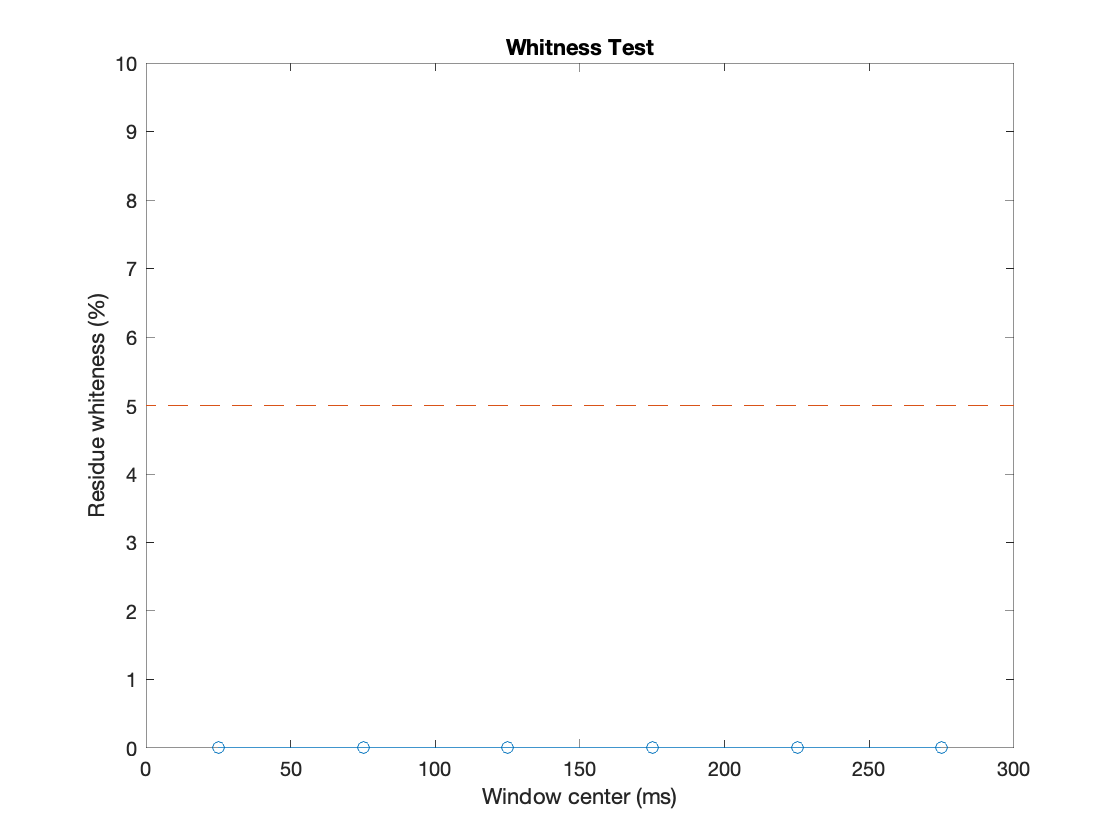

figure
plot(win_c, resid, '-o')
ylim([0, 10])
hold on
plot(xlim, [5, 5], '--')
title('Whitness Test')
xlabel('Window center (ms)')
ylabel('Residue whiteness (%)')